# Análise de sinais de voz

%%% Incia o ambiente matlab para uma sessão de análises

clear; clc; close all;

%%% Carrega o trabalho feito anteriormente e gravado no arquivo Voz.mat

load('Voz.mat') 


## Vissualizando o material que temos

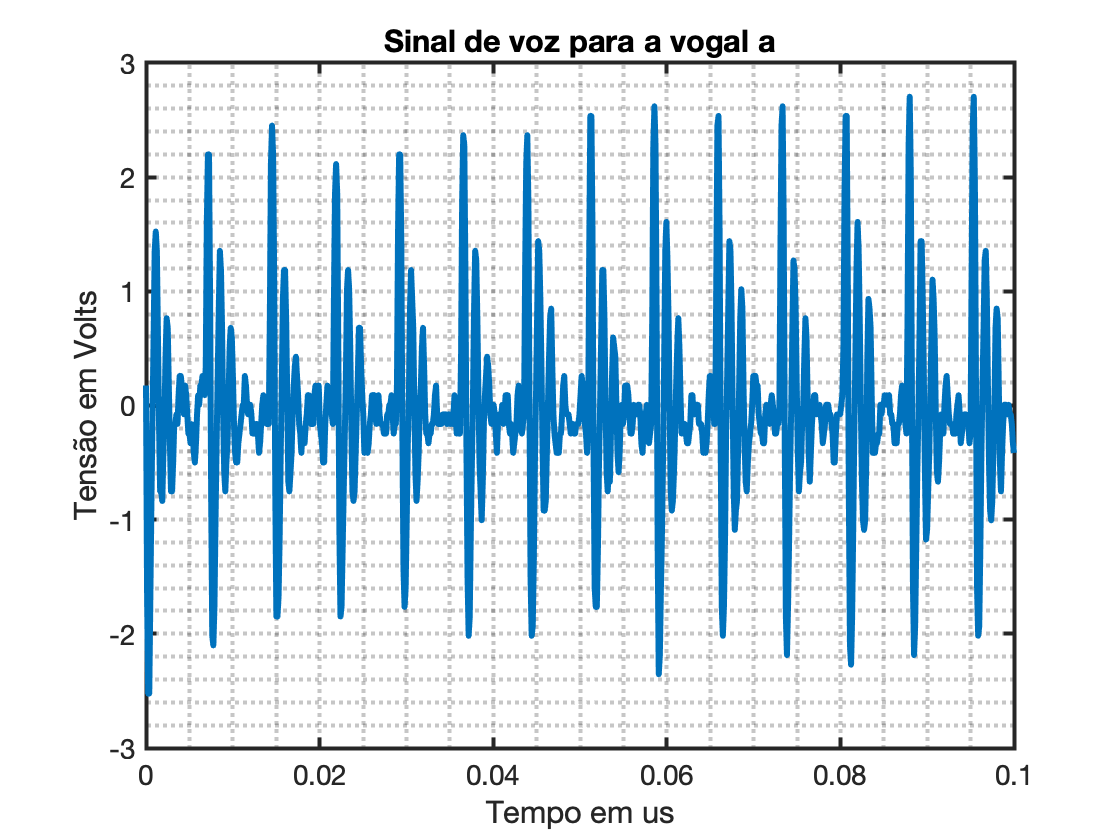


% Cria uma figura para a análise temporal

plot(t,Vp);
title('Sinal de voz para a vogal a');
xlabel('Tempo em us');
ylabel('Tensão em Volts'); 
grid minor

%%% modifica parâmetros do gráfico

set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);

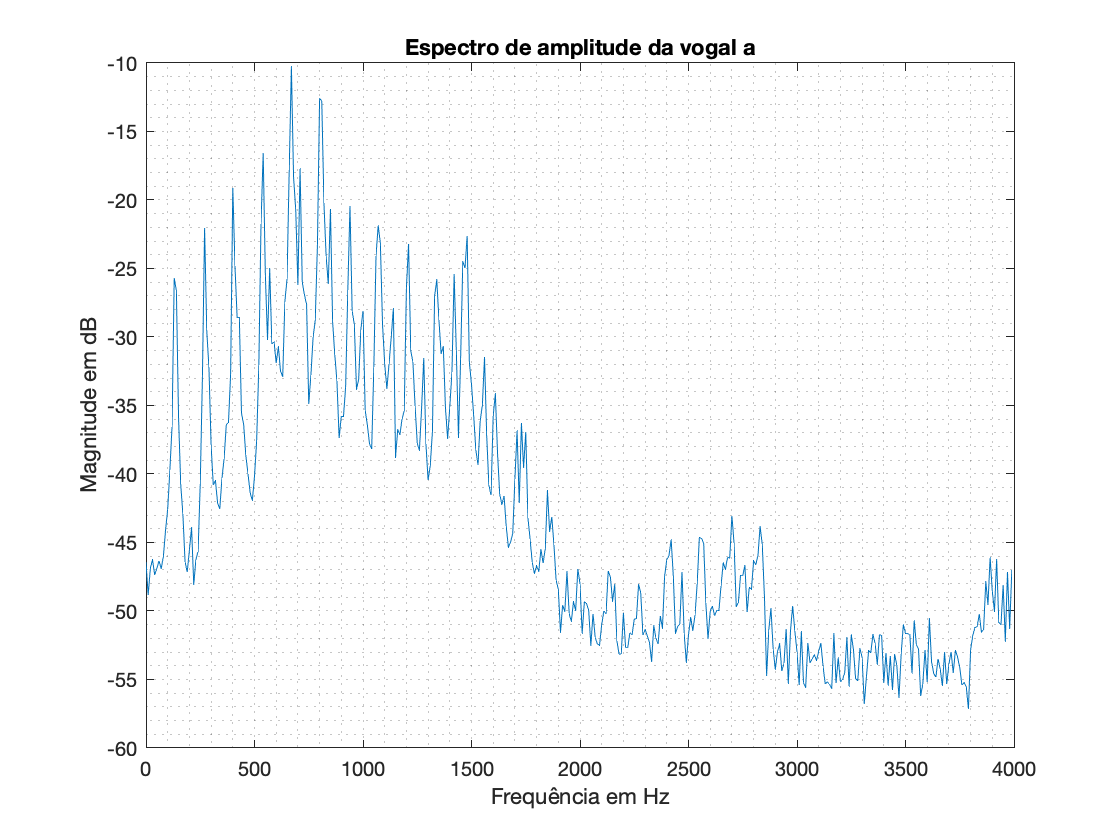


% Cria uma figura para a análise em frequência

plot(frequencia,Y0);
title('Espectro de amplitude da vogal a');
xlabel('Frequência em Hz');
ylabel('Magnitude em dB'); 
grid minor

## Modifica parâmetros do gráfico

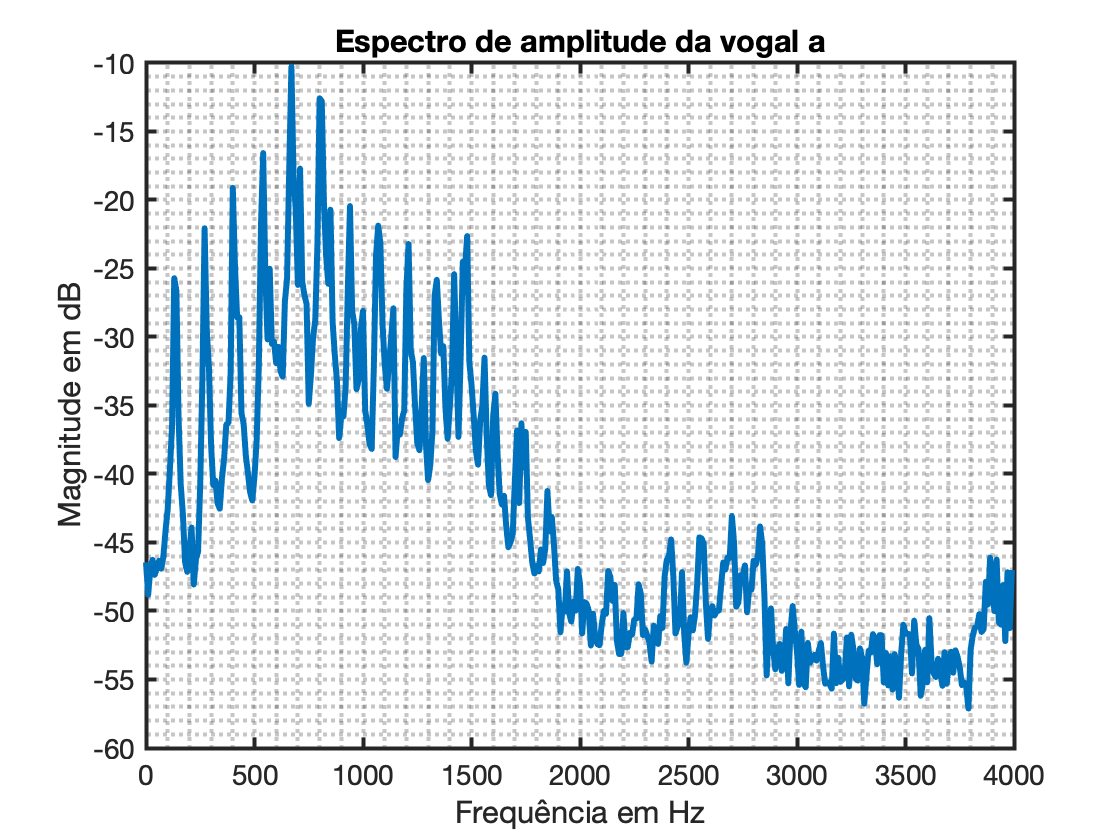

set(findall(gcf,'Type','line'),'LineWidth',3);
set(gca,'FontSize',14,'LineWidth',2);

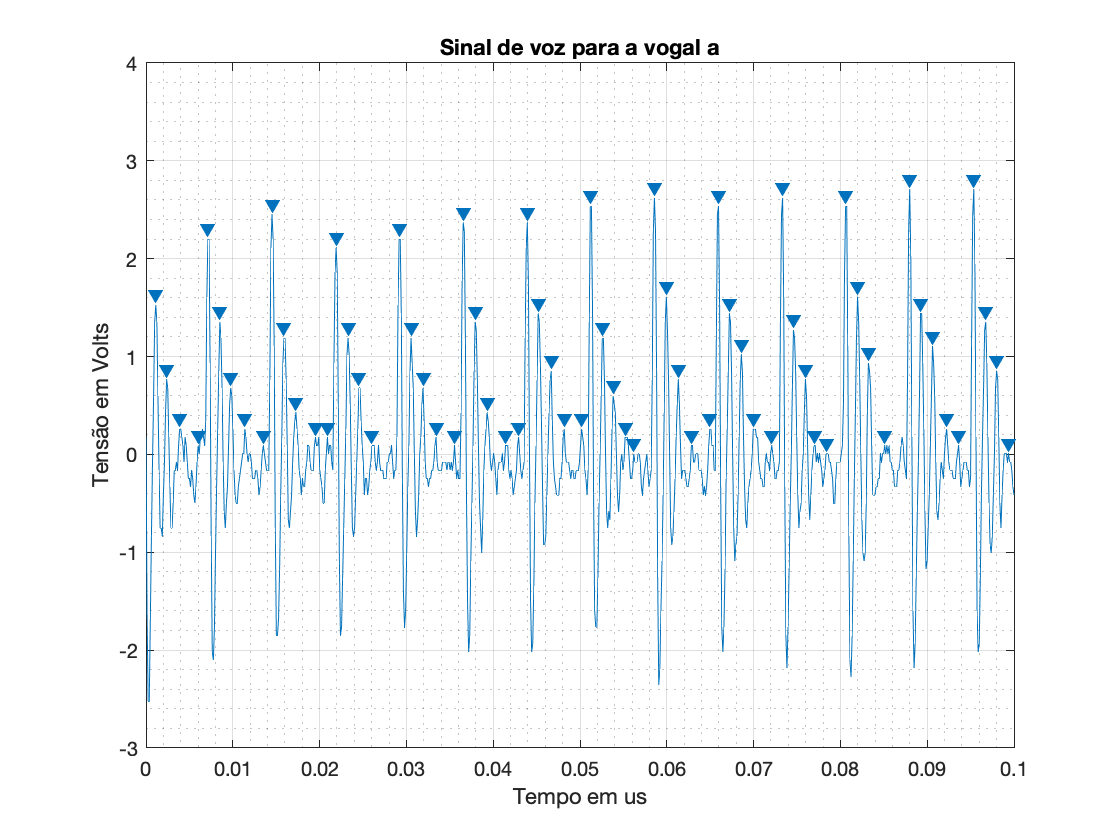


%%% Analisando os parâmteros graficamente

ti = 0.001126;  % começo do primeiro período inteiro
tf = 0.09537;   % fim do último período inteiro

T = (tf-ti)/13; % valor médio dentre os 13 períodos
f = inv(T);     % frequência associada a vibração gerada

findpeaks(Vp,t,'MinPeakDistance',0.001);

[vt,tp]=findpeaks(Vp,t,'MinPeakDistance',0.001);

Tm =mean(diff(tp));

title('Sinal de voz para a vogal a');
xlabel('Tempo em us');
ylabel('Tensão em Volts'); 
grid minor

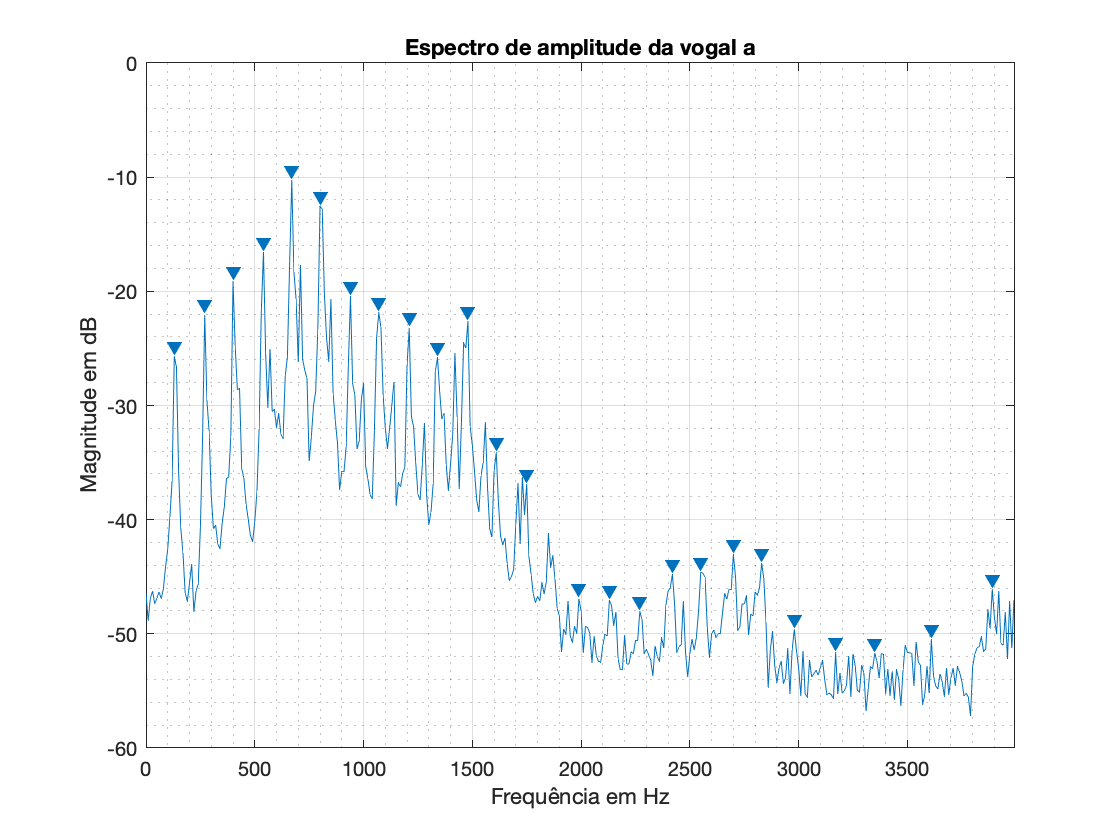


findpeaks(Y0,frequencia,'MinPeakDistance',0.9*f);

title('Espectro de amplitude da vogal a');
xlabel('Frequência em Hz');
ylabel('Magnitude em dB'); 
grid minor


[Md,fp]=findpeaks(Y0,frequencia,'MinPeakDistance',0.9*f);



## Harmônicas

H(1) = 130;
H(2) = 270;
H(3) = 400;
H(4) = 540;
H(5) = 670;
H(6) = 800;
H(7) = 940;
H(8) = 1070;

delta  =  diff(H);

%%% Valor médio da harmônica

Hm = mean(delta);

%%%% Formantes

FRM(1) = 670;
FRM(2) = 1480;
FRM(3) = 2700;



## Analisando o sinal de Voz

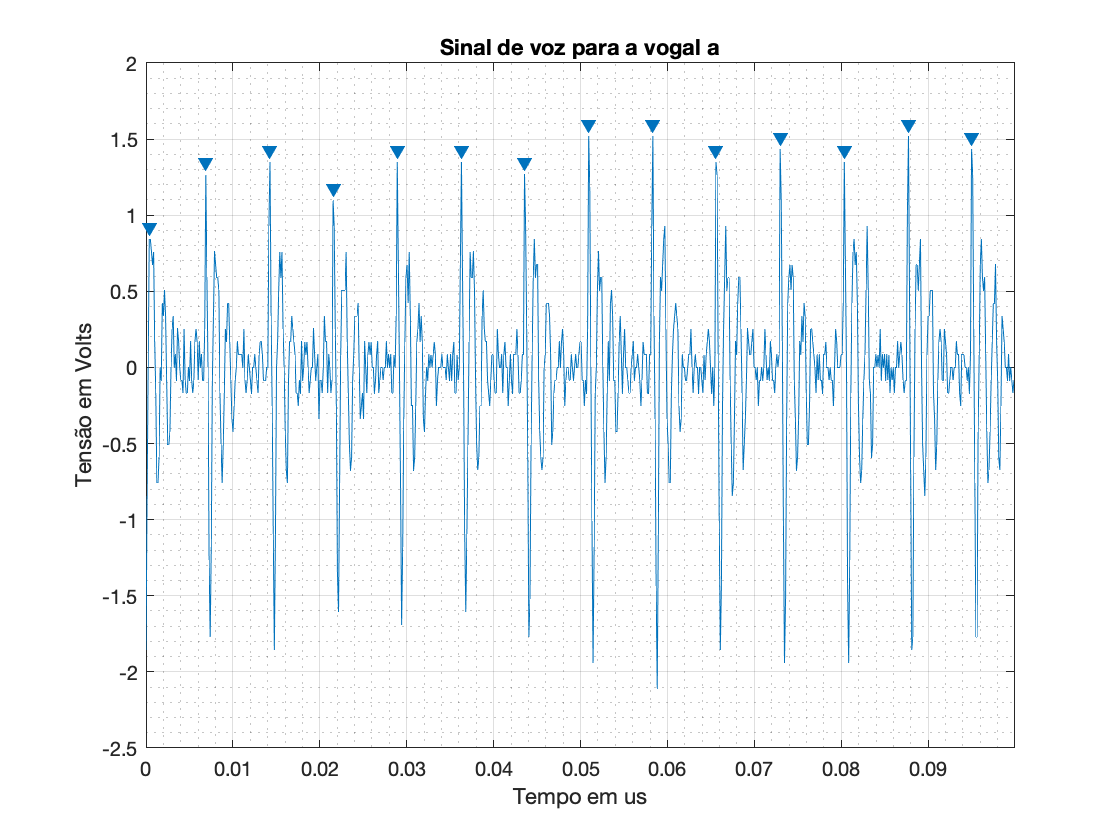

findpeaks(diff(Vp),t(1:end-1),'MinPeakDistance',0.001,'MinPeakDistance',0.005);
[vt,ip] = findpeaks(diff(Vp),t(1:end-1),'MinPeakDistance',0.001,'MinPeakDistance',0.005);

title('Sinal de voz para a vogal a');
xlabel('Tempo em us');
ylabel('Tensão em Volts'); 
grid minor

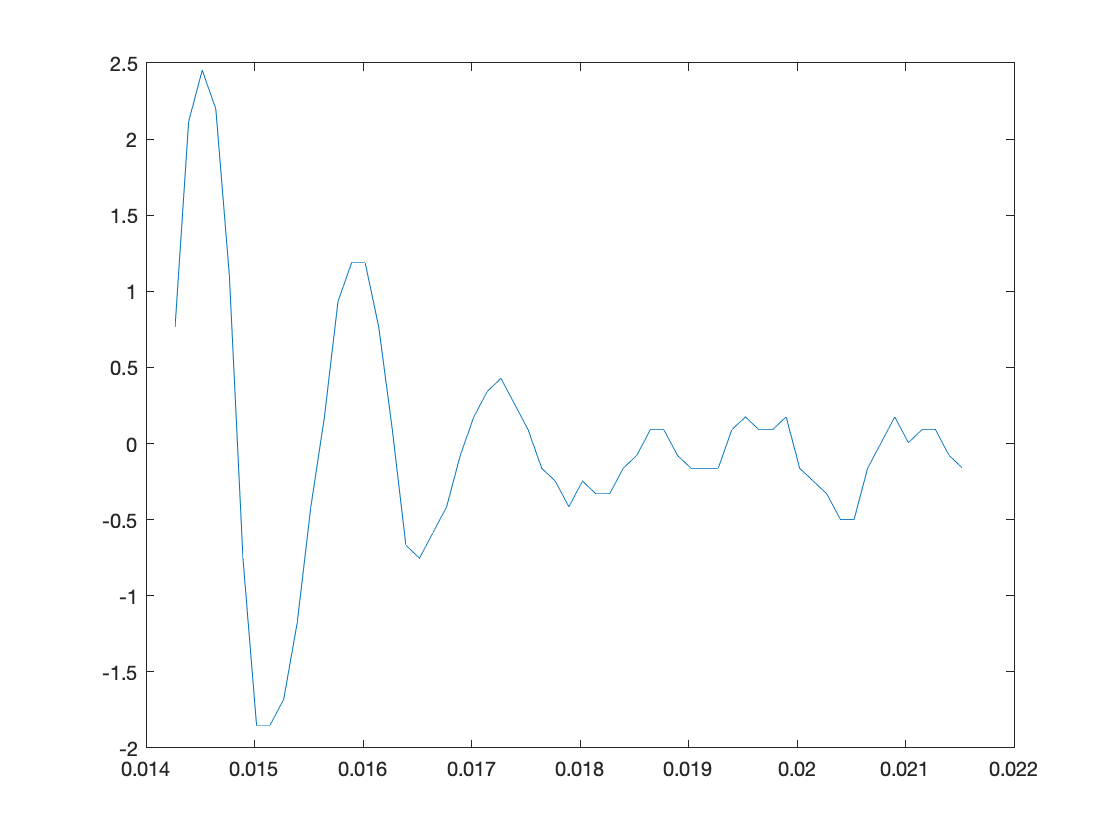


inicio =  find(t==ip(3));
fim    =  find(t==ip(4));

plot(t(inicio:fim),Vp(inicio:fim));


X = t(inicio:fim) - t(inicio);
Y = Vp(inicio:fim);

[vexp,texp] = findpeaks(Y,X,'MinPeakDistance',0.001);

f = fit(texp(1:3)',vexp(1:3),'exp1')

f =      General model Exp1:
     f(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       2.851  (1.041, 4.66)
       b =      -575.8  (-1290, 138.8)

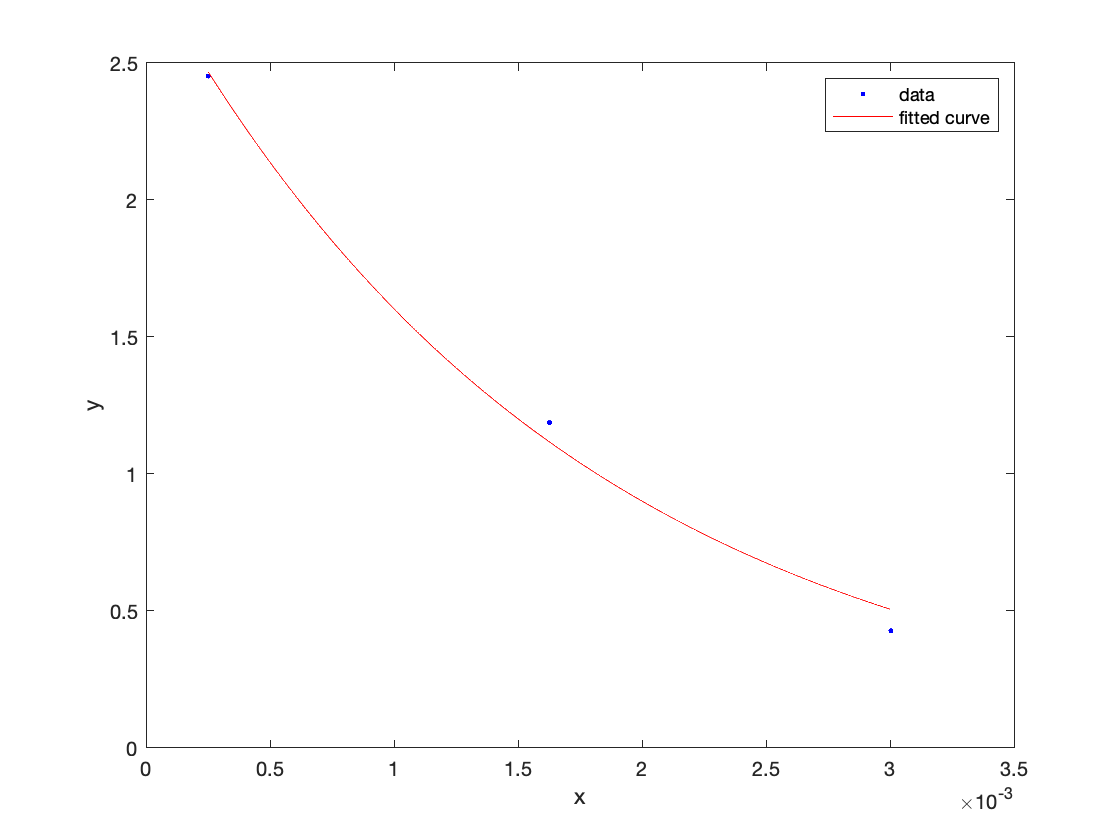

plot(f,texp(1:3)',vexp(1:3))

## Otimizando


x=[0 2.851 -575 730]';

% Plot the original and experimental data.

Y_new =  x(1) + x(2).*exp(x(3).*X).*sin(2*pi*x(4).*X)

Y_new =          0    1.4407    2.2515    2.2711    1.5996    0.5331   -0.5520   -1.3243   -1.5916   -1.3406   -0.7168    0.0406    0.6842    1.0341    1.0236    0.7042    0.2141   -0.2752   -0.6155   -0.7236   -0.5978   -0.3077    0.0368    0.3240    0.4744    0.4609    0.3095    0.0845   -0.1359   -0.2856


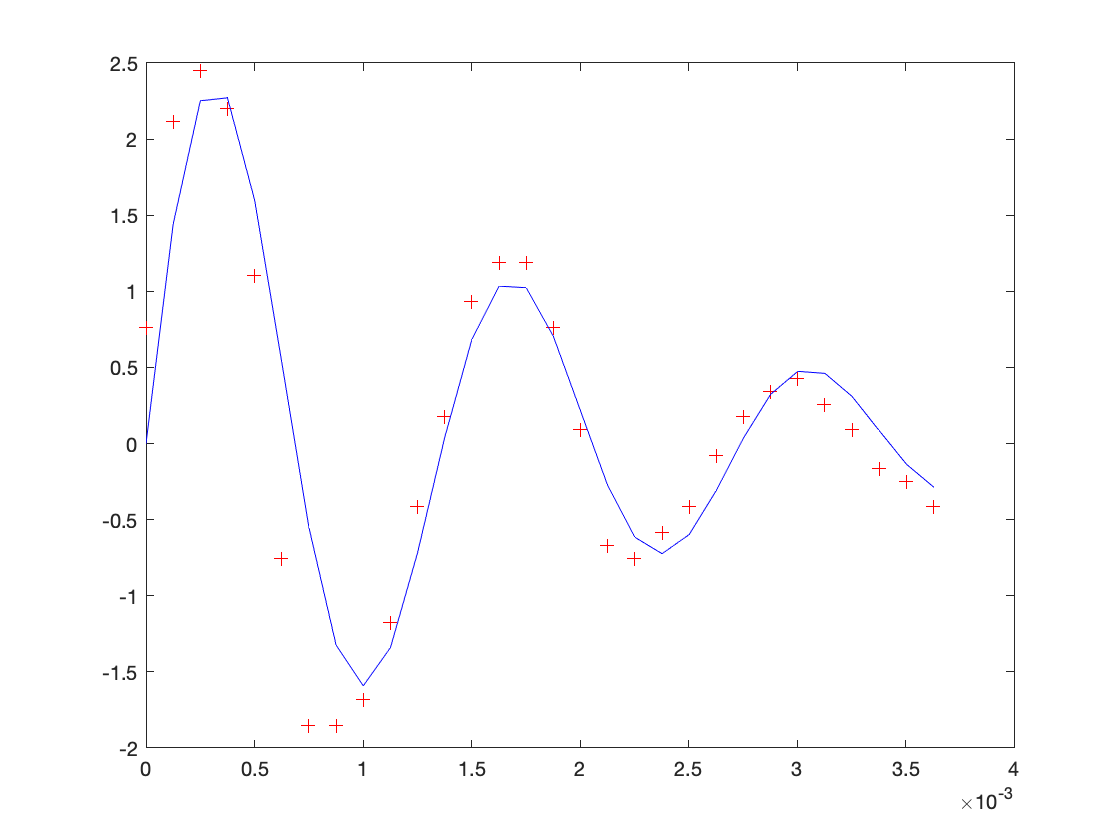


plot(X,Y,'+r',X,Y_new,'b')